f1 = [50 100];
f2 = 200:200:3200;
F = [f1,f2];
L1 = 5;
L2 = 5;
L3 = 8.3;
T = 10;
pgen = [7.26 7.17 7.27 7.19 7.09 7.20 7.22 6.96 7.08 7.07 6.95 6.81 6.85 6.81 6.57 6.48 6.65 6.31]/10;
Pgen = 10.^pgen;
pout1 = [7.16 6.80 6.66 5.90 5.75 5.59 5.28 4.90 4.68 4.28 3.90 3.62 3.58 3.10 2.71 2.66 2.35 2.02]/10;
Pout1 = 10.^pout1;
pout2 = [5.50 4.70 4.50 3.30 2.30 1.10 0.30 -0.8 -1.91 -2.7 -4.25 -4.96 -6.5 -6.75 -7.5 -8.05 -9.54 -10.60]/10;
Pout2 = 10.^pout2;
pout3 = [7.06 6.87 6.86 6.70 6.53 6.43 6.39 6.22 5.93 5.96 5.95 5.72 5.59 5.52 5.28 4.99 4.91 4.48]/10;
Pout3 = 10.^pout3;
% Cable loss
ldB1 = Pgen - Pout1;
LdB1 = 10 * log10(ldB1)

LdB1 =    -9.1677   -3.7095   -1.5560    1.2890    1.3304    2.1103    2.7862    2.7315    3.3594    3.8276    3.9790    3.9723    4.0847    4.4022    4.2700    4.1519    4.6328    4.2869


ldB2 = Pgen - Pout2;
LdB2 = 10 * log10(ldB2)

LdB2 =     2.4870    3.5425    4.0053    4.9109    5.3385    5.9768    6.2333    6.1639    6.4942    6.5861    6.6074    6.5110    6.6444    6.6143    6.3964    6.3242    6.5443    6.2206


ldB3 = Pgen - Pout3;
LdB3 = 10 * log10(ldB3)

LdB3 =    -6.2072   -4.5858   -3.1834   -2.5286   -2.0830   -0.6922   -0.3755   -1.0903    0.7468    0.6022    0.0817    0.2728    0.8611    0.9090    0.6690    1.1103    1.8367    1.6738


% damping factor
a1 = LdB1/L1

a1 =    -1.8335   -0.7419   -0.3112    0.2578    0.2661    0.4221    0.5572    0.5463    0.6719    0.7655    0.7958    0.7945    0.8169    0.8804    0.8540    0.8304    0.9266    0.8574


a2 = LdB2/L2

a2 =     0.4974    0.7085    0.8011    0.9822    1.0677    1.1954    1.2467    1.2328    1.2988    1.3172    1.3215    1.3022    1.3289    1.3229    1.2793    1.2648    1.3089    1.2441


a3 = LdB3/L3

a3 =    -0.7479   -0.5525   -0.3835   -0.3046   -0.2510   -0.0834   -0.0452   -0.1314    0.0900    0.0726    0.0098    0.0329    0.1037    0.1095    0.0806    0.1338    0.2213    0.2017


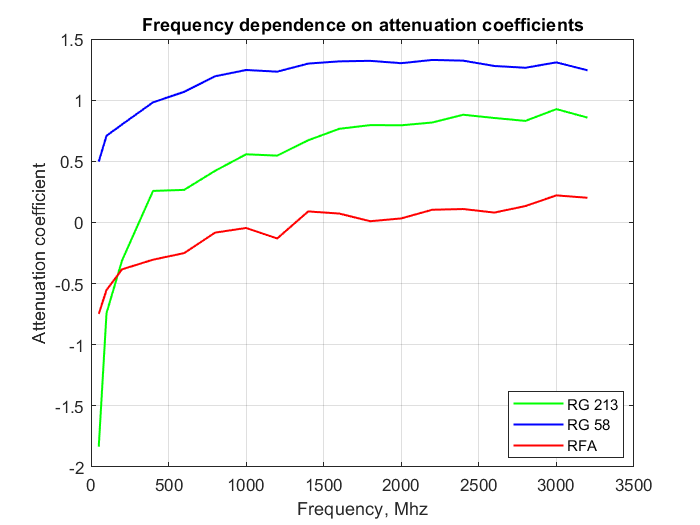


plot(F,a1,'g',F,a2,'b',F,a3,'r','linewidth',1.2)
title('Frequency dependence on attenuation coefficients')
xlabel('Frequency, Mhz');
ylabel('Attenuation coefficient');
legend({'RG 213';'RG 58';'RFA'},'Location','best');
grid on